# Design and Train YOLOv2 in MATLAB 

**What is a YOLOv2 Network**

**You only look once (YOLO)** is an object detection system targeted for real-time processing. It uses a single stage object detection network which is faster than other two-stage deep learning object detectors, such as regions with convolutional neural networks (Faster R-CNNs).

The YOLOv2 model runs a deep learning CNN on an input image to produce network predictions. The object detector decodes the predictions and generates bounding boxes.

## Step 1: Design YOLOv2 network layers

In this model we designed a custom YOLOv2 model layer by layer. The model starts by an input layer. Then the detection subnetwork contains a series of `Conv`, `Batch norm`, and `ReLu` layers, followed by the, [`yolov2TransformLayer`](https://www.mathworks.com/help/vision/ref/nnet.cnn.layer.yolov2transformlayer.html) and [`yolov2OutputLayer`](https://www.mathworks.com/help/vision/ref/nnet.cnn.layer.yolov2outputlayer.html) objects, respectively. [`yolov2TransformLayer`](https://www.mathworks.com/help/vision/ref/nnet.cnn.layer.yolov2transformlayer.html) transforms the raw CNN output into a form required to produce object detections. [`yolov2OutputLayer`](https://www.mathworks.com/help/vision/ref/nnet.cnn.layer.yolov2outputlayer.html) defines the anchor box parameters and implements the loss function used to train the detector.

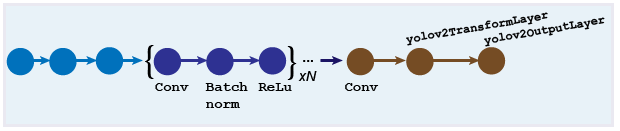

The` imageInputLayer` function is used to define the image input layer with minimum image size (128x128x3 used here). Use your best judgement based on the dataset and objects that need to be detected

inputLayer = imageInputLayer([128 128 3],'Name','input','Normalization','none');

`Set the convolution layer filter size to [3 3]. `This size is common in CNN architectures. `FilterSize` defines the size (height & width) of the local regions to which the neurons connect in the input.

filterSize = [3 3];

For the middle layers we followed the basic approach of [YOLO9000](https://arxiv.org/pdf/1612.08242.pdf) paper and used a a repeated batch of [Convolution2dLayer](https://www.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.convolution2dlayer.html?searchHighlight=Convolution2dLayer&s_tid=doc_srchtitle)`,`[Batch Normalization Layer](https://www.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.batchnormalizationlayer.html?searchHighlight=batchnormalizationlayer&s_tid=doc_srchtitle)`,`[RelU Layer](https://www.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.relulayer.html?searchHighlight=relu%20layer&s_tid=doc_srchtitle)` and `[Max Pooling Layer](https://www.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.maxpooling2dlayer.html?s_tid=doc_ta). Similar to the other classification models like VGG model we doubled the no of channels (`filterSize`) after every pooling step. We used batch normalization to stabilize training, speed up convergence and regularize the model. 

middleLayers = [
    convolution2dLayer(filterSize, 16, 'Padding', 1,'Name','conv_1',...
    'WeightsInitializer','narrow-normal')
    batchNormalizationLayer('Name','BN1')
    reluLayer('Name','relu_1')
    maxPooling2dLayer(2, 'Stride',2,'Name','maxpool1')
    convolution2dLayer(filterSize, 32, 'Padding', 1,'Name', 'conv_2',...
    'WeightsInitializer','narrow-normal')
    batchNormalizationLayer('Name','BN2')
    reluLayer('Name','relu_2')
    maxPooling2dLayer(2, 'Stride',2,'Name','maxpool2')
    convolution2dLayer(filterSize, 64, 'Padding', 1,'Name','conv_3',...
    'WeightsInitializer','narrow-normal')
    batchNormalizationLayer('Name','BN3')
    reluLayer('Name','relu_3')
    maxPooling2dLayer(2, 'Stride',2,'Name','maxpool3')
    convolution2dLayer(filterSize, 128, 'Padding', 1,'Name','conv_4',...
    'WeightsInitializer','narrow-normal')
    batchNormalizationLayer('Name','BN4')
    reluLayer('Name','relu_4')
    ];

## Step 2: Create layer graph for yolov2 network.

Combine the initial & middle layers and convert into a layer graph object in order to manipulate the layers

lgraph = layerGraph([inputLayer; middleLayers]);

Compute number of Classes based on Input data.

numClasses = size(trainingData,2)-1;

## Step 3: Define Anchor boxes

*Anchor boxes* are a set of predefined bounding boxes of a certain height and width. These boxes are defined to capture the scale and aspect ratio of specific object classes you want to detect and are typically chosen based on object sizes in your training datasets. You can define several anchor boxes, each for a different object size. The use of anchor boxes enables a network to detect multiple objects, objects of different scales, and overlapping objects. You can study in details about the [Basics of anchor boxes ](https://www.mathworks.com/help/vision/ug/anchor-box-basics.html)here. 

The anchor boxes is selected based on the scale and size of objects in the training data. You can [Estimate Anchor Boxes Using Clustering](https://www.mathworks.com/help/vision/ug/estimate-anchor-boxes-using-clustering-for-deep-learning.html) to determine a good set of anchor boxes based on the training data. Using this procedure, the anchor boxes for the dataset are:

open(fullfile("codeFiles","AnchorBoxes.m"));

Anchors = [71 94
    91 109
    81 94
    74 83];


## Step 4: Assemble YOLOv2 network

The [yolov2Layers](https://www.mathworks.com/help/vision/ref/yolov2layers.html?s_tid=doc_ta) function creates a YOLO v2 network, which represents the network architecture for YOLO v2 object detector.

`'relu_4'` is the feature extraction layer , The features extracted from this layer are given as input to the YOLO v2 object detection subnetwork. You can specify any network layer except the fully connected layer as the feature layer.

lgraph = yolov2Layers([128 128 3],numClasses,Anchors,lgraph,'relu_4');

Visualize the `lgraph` using the `network analyzer app.`

analyzeNetwork(lgraph);

## Step 5: Train the Network

Set a random seed to ensure example training reproducibility.

doTraining = true; 
% setting this flag to true will build and train a YOLOv2 detector
% false will load a pre-trained network


if doTraining
    rng(0);

Based on the size of the data set we train the network with the solver - stochastic gradient descent for 80 epochs with initial learning rate of 0.001 and mini-batch size of 16. We performed lower learning rate to give more time for training considering the size of data and adjusting the epoch and mini-batch size. The other approcah could be more epochs like 160 with a higher learning rate of 0.01.  Detailed Documentation to learn about all the options: [trainingOptions](https://www.mathworks.com/help/deeplearning/ref/trainingoptions.html?s_tid=doc_ta).

`ExecutionEnvironment` defines the Hardware resource for training network.

`DispatchInBackground` is used only when parallel training or multi-gpu environment. 

    options = trainingOptions('sgdm', ...
        'InitialLearnRate',0.001, ...
        'Verbose',true,'MiniBatchSize',50,'MaxEpochs',12,...
        'Shuffle','every-epoch','VerboseFrequency',50, ...
        'DispatchInBackground',true,...
        'ExecutionEnvironment','auto');

Call the YOLOv2 training function - [trainYOLOv2ObjectDetector](https://www.mathworks.com/help/vision/ref/trainyolov2objectdetector.html?s_tid=doc_ta)

    [detectorYolo2, info] = trainYOLOv2ObjectDetector(trainingData,lgraph,options);    
else
    load(fullfile("Utilities","detectorYoloV2.mat")); %pre-trained detector loaded from a MAT file
end

## Step 6: Detect ROI's with the detector

Create a table to hold the reults

results = table('Size',[height(TestData) 3],...
    'VariableTypes',{'cell','cell','cell'},...
    'VariableNames',{'Boxes','Scores', 'Labels'});

Initialize a Deployable Videl Player to view the image stream

depVideoPlayer = vision.DeployableVideoPlayer;

Loop through all the images in the  Validation set

for i = 1:height(TestData)
    
    % Read the image
    I = imread(TestData.imageFilename{i});
    
    % Run the detector.
    [bboxes,scores,labels] = detect(detectorYolo2,I);
    
    %
    if ~isempty(bboxes)
        I = insertObjectAnnotation(I,'Rectangle',bboxes,cellstr(labels));
        depVideoPlayer(I);
        pause(0.1);

    end    
    
    % Collect the results in the results table
    results.Boxes{i} = floor(bboxes);
    results.Scores{i} = scores;
    results.Labels{i} = labels;
    
end

## Step 6: Compute Evaluation metrics and plot the results

threshold =0.5;

To evaluate the precision metrics we use [evaluateDetectionPrecision](https://www.mathworks.com/help/vision/ref/evaluatedetectionprecision.html) function. This function here returns the data points for plotting the precison-recall curve using the given input arguments and the threshold value. 

[ap, recall, precision] = evaluateDetectionPrecision(results, TestData(:,2:end),threshold);

To evaluate miss rate metric for object detection we use the function [evaluateDetectionMissRate](https://www.mathworks.com/help/vision/ref/evaluatedetectionmissrate.html?s_tid=doc_ta)`.`This function returns the log average -miss rate of the results compared to the groundTruthData and data points fpr plotting the log miss rate to false positives per image.  

[am,fppi,missRate] = evaluateDetectionMissRate(results, TestData(:,2:end),threshold);

Plot the evaluation metrics for each class

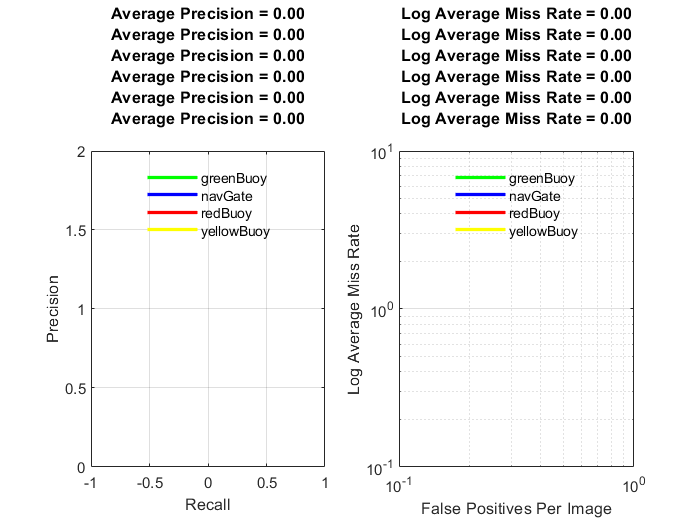

subplot(1,2,1);
plot(recall{1,1},precision{1,1},'g-','LineWidth',2, "DisplayName",'greenBuoy');
hold on;
plot(recall{2,1},precision{2,1},'b-','LineWidth',2, "DisplayName",'navGate');
hold on;
plot(recall{3,1},precision{3,1},'r-','LineWidth',2, "DisplayName",'redBuoy');
hold on;
plot(recall{4,1},precision{4,1},'y-','LineWidth',2, "DisplayName",'yellowBuoy');
hold off;

xlabel('Recall');
ylabel('Precision');
title(sprintf('Average Precision = %.2f\n', ap))
legend('Location', 'best');
legend('boxoff')
grid on

subplot(1,2,2);
loglog(fppi{1,1}, missRate{1,1},'-g','LineWidth',2, "DisplayName",'greenBuoy');
hold on;
loglog(fppi{2,1}, missRate{2,1},'-b','LineWidth',2,"DisplayName",'navGate');
hold on;
loglog(fppi{3,1}, missRate{3,1},'-r','LineWidth',2, "DisplayName",'redBuoy');
hold on;
loglog(fppi{4,1}, missRate{4,1},'-y','LineWidth',2, "DisplayName",'yellowBuoy');
hold off;

xlabel('False Positives Per Image');
ylabel('Log Average Miss Rate');
title(sprintf('Log Average Miss Rate = %.2f\n', am))
legend('Location', 'best');
legend('boxoff')
grid on